%Init
clear();
close all;
tic;

%get landing page html
headurl = "https://www.spiegel.de/auto/fahrberichte/p1/";
fullhead = webread(headurl);
tree = htmlTree(fullhead);

%get pages
pagecount = str2double(cell2mat(erase(extractBetween(fullhead,'Seite 1','</div>'),'/')));
clear("fullhead");

%get html of all pages
attr = "href";
selector = "A";
for i=1:pagecount(1,1)
    headurl = "https://www.spiegel.de/auto/fahrberichte/p"+i+"/";
    fullhead = webread(headurl);
    tree = htmlTree(fullhead);
    clear("fullhead");

    subtrees = findElement(tree,selector);
    strurls = getAttribute(subtrees,attr);
    clear("subtrees","tree");

    idx = contains(strurls,"https://www.spiegel.de/auto/fahrberichte/");
    closeurls = strurls(idx,1);
    closeurls = sortrows(closeurls,1,"ascend");
    actualurls = unique(closeurls,'rows');
    actualurls(1:2,:) = [];
    if i==1
        allurls = actualurls;
    else
        allurls = [allurls;actualurls];
    end
    clear("headurl","strurls","idx","closeurls","actualurls");
end
allurls = sortrows(allurls,1,"ascend");
clear("pagecount","i","attr","selector");

%Get Keywords
vartypes = ["string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string" "string"];
keys = table('Size',[height(allurls) 20],'VariableTypes',vartypes);
for i=1:height(allurls)
    url = allurls(i,1);
    fullhtml = webread(url);
    tree = htmlTree(fullhtml);

    raw = tree.string;
    str = extractBetween(raw,'name="news_keywords" content="','"/>');
    str = unique(split(str,', '))';

    keys(i,1:length(str)) = array2table(str);
    clear("tree","fullhtml","url","str","raw");
end
clear("i","allurls","vartypes");

%modify table
keysarray = table2array(keys);
keys1Darray = keysarray(:);
onlywords = rmmissing(keys1Darray);
clear("keysarray","uniquekeys","keys","keys1Darray");

%count keywords
[GC,GN] = groupcounts(onlywords);
tabelle = table(GN,GC,'VariableNames',["Keywords" "Haeufigkeit"]);
tabelleSorted = sortrows(tabelle,2,"descend");
clear("GC","GN","onlywords")

Elapsed time is 1016.838698 seconds.


toc

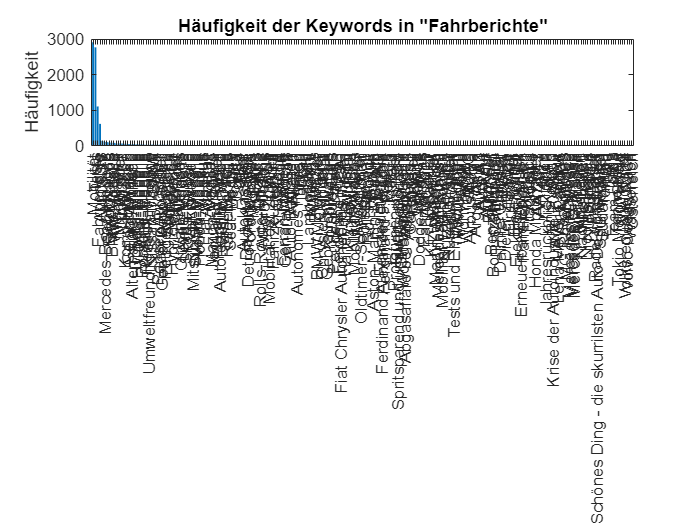

%Darstellung
X = categorical(tabelleSorted.Keywords);
X = reordercats(X,tabelleSorted.Keywords);
Y = tabelleSorted.Haeufigkeit;
bar(X,Y)
title('Häufigkeit der Keywords in "Fahrberichte"')
ylabel("Häufigkeit");

%xlabel("Keywords");
clear("tabelleSorted","tabelle","X","Y")